# Quantization Introduction

[https://www.mathworks.com/solutions/deep-learning/embedded-ai.html](https://www.mathworks.com/solutions/deep-learning/embedded-ai.html)

**Hardware: **CPUs, Microcontroller, GPUs, NPUs, FPGA, SoCs

**Question: **What is the main limitation when dealing with hardware?

[https://www.mathworks.com/help/deeplearning/ref/deepnetworkquantizer-app.html](https://www.mathworks.com/help/deeplearning/ref/deepnetworkquantizer-app.html)

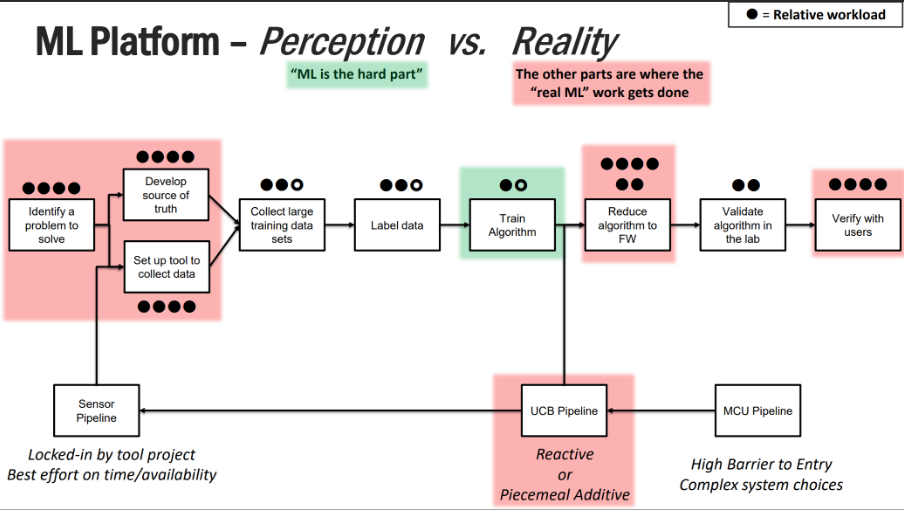

**App: **Deep Network Quantizer

**Add-Ons:**

- Deep Learning Toolbox Model Compression Library

- MATLAB Coder Interface for Deep Learning

**Goals & Benefits: **

- Reduce memory requirements of DNN & memory bandwidth

- Quantize model into 8-bit fixed point so that hardware can understand (Most hardware uses INT8)

- Reduce the processor overhead & data movement (Reduce computation energy consumption)

- Increase inference throughput (1x FP32 = 4x INT8 cycle)

- Enable deployment on resource-constrained hardware

- Maintain acceptable accuracy under reduced precision

**Issue:**

Limited range and precision after quantize

- precision loss (rounding error)

- underflow (value is smaller than smallest value, saturates to 0)

- overflow (value larger than largest value, saturates to largest value in data type)

deepNetworkQuantizer

## Understanding decimal/binary conversion

1.5  (decimal) = 1.1 (base 2)

totalValue = 0; % Initialize total value

for i=-6:1:6
    if i < 0
        binaryRepresentation = dec2bin(2^(-i), 8); % Convert to binary with 8 bits for negative values
        binaryRepresentation = ['1' binaryRepresentation(2:end)]; % Set MSB as sign bit
    else
        binaryRepresentation = dec2bin(2^i, 8); % Convert to binary with 8 bits for positive values
    end
    fprintf('2^%d= %f, Binary: %s\n', i, 2^i, binaryRepresentation);
    totalValue = totalValue + 2^i; % Sum the total value of decimal
end

2^-6= 0.015625, Binary: 11000000
2^-5= 0.031250, Binary: 10100000
2^-4= 0.062500, Binary: 10010000
2^-3= 0.125000, Binary: 10001000
2^-2= 0.250000, Binary: 10000100
2^-1= 0.500000, Binary: 10000010
2^0= 1.000000, Binary: 00000001
2^1= 2.000000, Binary: 00000010
2^2= 4.000000, Binary: 00000100
2^3= 8.000000, Binary: 00001000
2^4= 16.000000, Binary: 00010000
2^5= 32.000000, Binary: 00100000
2^6= 64.000000, Binary: 01000000



fprintf('Largest decimal and precision: %f\n', totalValue); % Display the total value

Largest decimal and precision: 127.984375


## **Demo**

load squeezedlnetmerch
net

net =   dlnetwork with properties:

         Layers: [67×1 nnet.cnn.layer.Layer]
    Connections: [74×2 table]
     Learnables: [52×3 table]
          State: [0×3 table]
     InputNames: {'data'}
    OutputNames: {'prob'}
    Initialized: 1

  View summary with summary.



unzip('MerchData.zip');
imds = imageDatastore('MerchData', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');
[calData, valData] = splitEachLabel(imds, 0.7, 'randomized');
aug_calData = augmentedImageDatastore([227 227], calData);
aug_valData = augmentedImageDatastore([227 227], valData);

Calibration = Run data through floating-point network only to measure numeric ranges

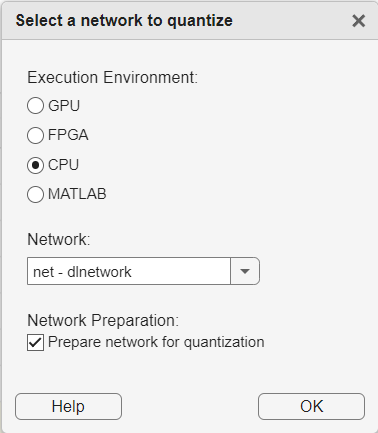

Network Preparation:

- **Checked** → MATLAB rewrites the network so calibration + quantization make sense

- **Unchecked** → You promise the network is already quantization-compatible

Quantize Residual Network Trained for Image Classification and Generate CUDA Code:

[https://www.mathworks.com/help/deeplearning/ug/quantize-a-residual-network-trained-for-image-classification-and-generate-cuda-code.html](https://www.mathworks.com/help/deeplearning/ug/quantize-a-residual-network-trained-for-image-classification-and-generate-cuda-code.html)